clc
clear 
close all

defines

load s20/data220.mat
plot(t,y);
hold on
s = tf('s');

najdenie prvych extremov

coefficients = polyfit(t, y, 11);
% Generate a polynomial function from the coefficients
fitted_function = polyval(coefficients, t);

[peaks, peak_indices] = findpeaks(fitted_function);

% Find valleys and their indices
[valleys, valley_indices] = findpeaks(-fitted_function);

% First maximum and its index
[first_max, max_index] = max(peaks);
first_max_index = peak_indices(1);

% First minimum and its index
[first_min, min_index] = min(valleys);
first_min_index = valley_indices(1);

y1 = y(first_max_index); 
t1 = t(first_max_index);
y2 = y(first_min_index);
t2 = t(first_min_index);

first_min_index = valley_indices(2);
first_max_index = peak_indices(2);
y12 = y(first_max_index); 
t12 = t(first_max_index);
y22 = y(first_min_index);
t22 = t(first_min_index);
plot(t,fitted_function);
hold on;
% plot(t1,y1,"rx")
% plot(t2,y2,"rx")
% plot(t12,y12,"rx")

Postup metoda 1.

K = y(end);
M = (y1-y2)/y1;
ksi = abs(log(M)/sqrt(pi^2+log(M)^2));
P = sqrt(1-ksi^2);
omega_0 = pi/((t2-t1)*sqrt(1-ksi^2));
T = 1/omega_0;
F = K*omega_0^2/(s^2 + 2*ksi*omega_0*s +omega_0^2);
t_model = linspace(0, t(end), 10000);
y_model = step(F,t_model);

plot(t_model, y_model);

Postup metoda 2.

c = (1/pi)*log(y1/K-1);
ksi = -c/sqrt(1+c^2);
delta_t = t12-t1;
T = delta_t/(2*pi*sqrt(1+c^2));
omega_0 = 1/T;
F = K*omega_0^2/(s^2 + 2*ksi*omega_0*s +omega_0^2);
t_model = linspace(0, t(end), 10000);
y_model = step(F,t_model);

plot(t_model, y_model);

postup metoda 3.

A1 = y1 - y(end);
A2 = y12 - y(end);
delta = A1/A2;
ksi = log(delta)/sqrt(log(delta)^2+4*pi^2);
delta_t = t12-t1;
T = delta_t/(2*pi)*sqrt(1-ksi^2);
omega_0 = 1/T;
F = K*omega_0^2/(s^2 + 2*ksi*omega_0*s +omega_0^2);
t_model = linspace(0, t(end), 10000);
y_model = step(F,t_model);

plot(t_model, y_model);

S dopravnym oneskorenim

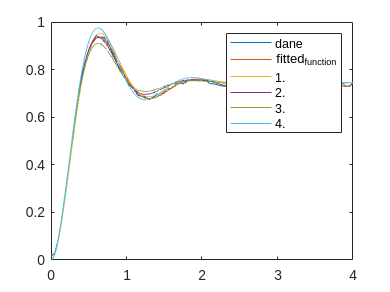

a1 = y1-y2;
a2 = y12 - y2;
n = 2;
K = y(end);
ksi = -(log(a2/a1))/sqrt(pi^2+log(a2/a1)^2);
T = 1/(pi*n)*(t12 - t1)*sqrt(1-ksi^2);
omega_0 = 1/T;
D = 1/n*(t1-t2)-(n+1)/(2*n)*(t12-t1);

F = K*omega_0^2/(s^2 + 2*ksi*omega_0*s +omega_0^2);
t_model = linspace(0, t(end), 10000);
y_model = step(F,t_model);

plot(t_model, y_model);
legend("dane","fitted_function","1.","2.","3.","4.")